clear;  close all;    

% We first Define 'para' structure as a container for parameters
para = struct();

% ---------------------------------------------
% |        1         |  2  |        3         |
% |     Anode        | Sep.|     Cathode      |]]
% |                  |     |                  |
% ---------------------------------------------

%% Constants 
    para.R  = 8.314;      % Gas constant [J/(mol·K)]
    para.F  = 96487;      % Faraday constant [C/mol]
    para.T_ref = 25 + 273.15;  % Reference temperature [K]

    % Cell nominal capacity [A·h]
    para.C_nom = 4.2;

    % Current collector resistance [Ω·m^2]
    para.Rc = 20e-4; 
    
%% Battery geometry
    para.thick1 = 73.50e-6;  % anode thickness [m]
    para.thick2 = 25.00e-6;  % separator thickness [m]
    para.thick3 = 70.00e-6;  % cathode thickness [m]
    para.L = para.thick1 + para.thick2 + para.thick3;  % total cell thickness [m]
    para.As = 0.0982;  % electrode active surface area [m^2]

%% Electrolyte
    para.ce_avg = 1000; %electrolyte average concentrations [mol/m^3]

%% Active porous material
    % Radii of solid particles
    para.Rs1 = 12.5e-6;  % anode particle radius [m]
    para.Rs3 = 8.5e-6;   % cathode particle radius [m]

    % Volume fractions of active material
    para.eps1s = 0.5052;  % anode
    para.eps3s = 0.5500;  % cathode

    % Specific interfacial surface area in porous electrodes [m^2/m^3]
    para.as1 = (3*para.eps1s)/para.Rs1;  % anode
    para.as3 = (3*para.eps3s)/para.Rs3;  % cathode

    % Max solid-phase concentrations [mol/m^3]
    para.cs1_max = 30556;  
    para.cs3_max = 51555;

    % Stoichiometry bounds determined by electrode balancing and ageing
    c_age = 1;
    % Stoichiometry bounds determined by electrode balancing and ageing
    para.soc0_a = 0.0068+c_age*0.01; % anode stoichiometry at 0% SOC
    para.soc1_a = 0.7560-c_age*0.01; % anode stoichiometry at 100% SOC
    para.soc0_c = 0.8933+c_age*0.01; % cathode stoichiometry at 0% SOC
    para.soc1_c = 0.4650-c_age*0.01; % cathode stoichiometry at 100% SOC


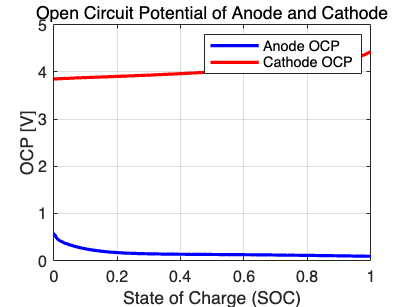

% Diffusion coefficients (reference at 25 degree) [m^2/s]
    para.Ds1_ref = 3.9e-14;  
    para.Ds3_ref = 1.0e-14;
    
% Reaction rate constants (reference at 25 degree) [m^(2.5)·mol^(-0.5)·s^(-1)]
    para.k1_ref = 1.764e-11;
    para.k3_ref = 6.667e-11;

% OCP polynomials (Graphite & LiCoO2)
% We'll store them as function handles that take stoichiometry x or y.
    para.U_ocp_anode = @(theta) ( ...
        0.7222 + 0.1387*theta + 0.0290*sqrt(theta) - 0.0172./theta + ...
        0.0019./(theta.^(1.5)) + 0.2808.*exp(0.90 - 15*theta) - ...
        0.7984.*exp(0.4465*theta - 0.4108) );
    
    para.U_ocp_cathode = @(theta) ( ...
       (-4.656 + 88.669*theta.^2 - 401.119*theta.^4 + 342.909*theta.^6 ...
        - 462.471*theta.^8 + 433.434*theta.^10) ./ ...
       (-1 + 18.933*theta.^2 - 79.532*theta.^4 + 37.311*theta.^6 ...
        - 73.083*theta.^8 + 95.96*theta.^10) );
SOC = linspace(0, 1, 100);

% Map SOC to stoichiometry
stoich_anode = para.soc0_a + SOC * (para.soc1_a - para.soc0_a);
stoich_cathode = para.soc0_c + SOC * (para.soc1_c - para.soc0_c);

% Compute OCP for anode and cathode
U_anode = para.U_ocp_anode(stoich_anode);
U_cathode = para.U_ocp_cathode(stoich_cathode);

% Compute Open Circuit Voltage (OCV) within stoichiometry limits
OCV = U_cathode - U_anode;

% Plot OCP curves for anode and cathode
figure;
plot(SOC, U_anode, 'b', 'LineWidth', 2); hold on;
plot(SOC, U_cathode, 'r', 'LineWidth', 2);
legend('Anode OCP', 'Cathode OCP');
xlabel('State of Charge (SOC)'); ylabel('OCP [V]');
title('Open Circuit Potential of Anode and Cathode');
grid on;

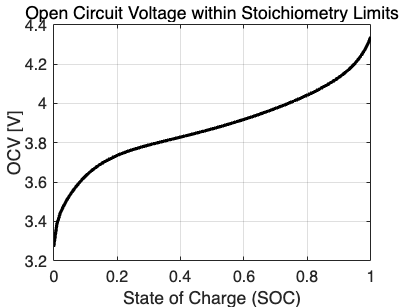


% Plot OCV within stoichiometry limits
figure;
plot(SOC, OCV, 'k', 'LineWidth', 2);
xlabel('State of Charge (SOC)'); ylabel('OCV [V]');
title('Open Circuit Voltage within Stoichiometry Limits');
grid on;

function dcdt = diffusion_sphere(c, R, D_ref, N)
    % c: vector of length N+1
    % R: particle radius
    % D_ref: diffusion coefficient
    % N: # of sub-intervals in radial discretization
    
    dr = R / N;
    r  = linspace(0, R, N+1)';
    
    dcdt = zeros(size(c));
    
    % Interior nodes
    for i = 2:N
        dcdt(i) = D_ref * ( ...
            (c(i+1) - 2*c(i) + c(i-1)) / dr^2 + ...
            (2/r(i)) * (c(i+1) - c(i-1)) / (2*dr) );
    end
    
    % Boundary at r=0 (due to symmetry)
    dcdt(1) = 2 * D_ref * ...
            (c(2) - c(1)) / dr^2;  % or a specialized second-order approach
end

function dcdt = spm_ode_system(~, x, para)
    % Unpack states
    Nn = para.Nr_anode;
    Np = para.Nr_cathode;
    
    c_n = x(1:Nn+1);                       % anode concentration profile
    c_p = x(Nn+2 : Nn+1 + (Np+1));         % cathode concentration profile
    
    % Initialise dxdt
    dcdt = zeros(size(x));
    
    % Compute diffusion in anode
    dc_n = diffusion_sphere(c_n, para.Rs1, para.Ds1_ref, Nn);
    
    % Compute diffusion in cathode
    dc_p = diffusion_sphere(c_p, para.Rs3, para.Ds3_ref, Np);
    
    % Flux boundary condition from the applied current
    
    % Negative sign for anode if current is extraction of Li
    flux_n = para.I_app / para.F / para.thick1;  % [mol/(m^2·s)]
    flux_p = -para.I_app / para.F / para.thick3;  % same magnitude, but direction is different
    
    % Apply boundary condition at the outer radius:
    dc_n(end) = dc_n(end) - flux_n;  % anode
    dc_p(end) = dc_p(end) - flux_p;  % cathode
    
    % Combine
    dcdt(1:Nn+1) = dc_n;
    dcdt(Nn+2 : Nn+1+(Np+1)) = dc_p;
end

Crate = -1;                              % e.g., 1C = current rate that allows full discharge in 1 hour
I_app = Crate * para.C_nom / para.As;    % applied density [A/m^2];             
para.I_app = -I_app;                     % store in para
para.time_span = [0, 3600];              % 1-hour if 1C
para.T = 273 + 25;                       % room temperature

% uniform Li concentration in anode/cathode
% by convention, I_app > 0 is charging and < 0 discharging
    if I_app >= 0
        c_n0 = para.soc0_a * para.cs1_max;  % anode
        c_p0 = para.soc0_c * para.cs3_max;  % cathode
    else
        c_n0 = para.soc1_a * para.cs1_max;  
        c_p0 = para.soc1_c * para.cs3_max; 
    end

    para.Nr_anode = 30; %number of discreatisation points
    para.Nr_cathode = 30;
    x0 = [ repmat(c_n0, para.Nr_anode+1, 1); ...
           repmat(c_p0, para.Nr_cathode+1, 1) ];


opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
[t_sol, x_sol] = ode15s(@(t,x) spm_ode_system(t, x, para), para.time_span, x0, opts);

% extract the ion concentrations in solid
% Do you want how to find the surface concentration?
c_n_all = x_sol(:, 1:para.Nr_anode+1);
c_p_all = x_sol(:, para.Nr_anode+2 : para.Nr_anode+1 + (para.Nr_cathode+1));

V_cell = zeros(size(t_sol));
for k = 1:length(t_sol)
    V_cell(k) = compute_terminal_voltage(x_sol(k,:)', para);
end

function V_cell = compute_terminal_voltage(x, para)
    % Unpack 
    Nn = para.Nr_anode;
    Np = para.Nr_cathode;
   
    c_n_surf = x(Nn+1);           % anode surface concentration
    c_p_surf = x(Nn+1 + Np+1);    % cathode surface concentration
    
    % Compute surface stoichiometries
    x1 = c_n_surf / para.cs1_max;
    y3 = c_p_surf / para.cs3_max;
    
    % OCP
    U_n = para.U_ocp_anode(x1);
    U_p = para.U_ocp_cathode(y3);
    
    % Internal/contact resistance drop
    IR_drop = para.Rc * para.I_app; % voltage drop [V] = [A/m^2]*[Ω·m^2]
% Overpotentials (very simplified or zero for demonstration)
    i_0_n = para.k1_ref*para.F.*(para.ce_avg.^0.5).*(c_n_surf.^0.5).*(para.cs1_max-c_n_surf).^0.5;  % at anode
    i_0_p = para.k3_ref*para.F.*(para.ce_avg.^0.5).*(c_p_surf.^0.5).*(para.cs3_max-c_p_surf).^0.5;  % at cathode
    eta_n = (2*para.R*para.T/para.F).*asinh(-0.5*para.I_app/para.as1/para.thick1./i_0_n);
    eta_p = (2*para.R*para.T/para.F).*asinh( 0.5*para.I_app/para.as3/para.thick3./i_0_p);
    

    V_cell = U_p - U_n - IR_drop - eta_n - eta_p;
end


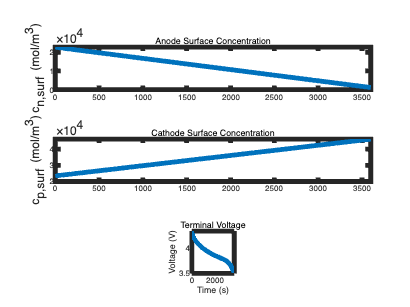

% Example plot
lw = 3; % line width for the curves

figure(); 
subplot(3,1,1);
plot(t_sol, c_n_all(:,end), 'LineWidth',lw);
ylabel('c_{n,surf} (mol/m^3)');
xlim([0 3600]);
title('Anode Surface Concentration');
set(gca, 'FontSize', 5, 'LineWidth', 3, 'Box', 'on');

subplot(3,1,2);
plot(t_sol, c_p_all(:,end), 'LineWidth',lw);
ylabel('c_{p,surf} (mol/m^3)');
xlim([0 3600]);
title('Cathode Surface Concentration');
set(gca, 'FontSize', 5, 'LineWidth', 3, 'Box', 'on');

subplot(3,1,3);
plot(t_sol, V_cell, 'LineWidth',lw);
xlabel('Time (s)'); ylabel('Voltage (V)');
title('Terminal Voltage');
axis square;
xlim([0 3600]);
set(gca, 'FontSize', 5, 'LineWidth', 3, 'Box', 'on');

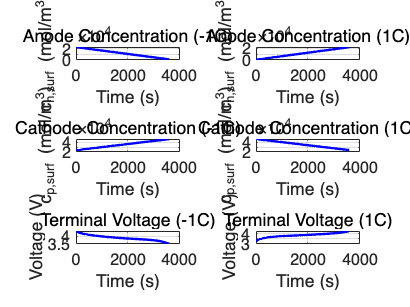

% 充放电倍率
Crates = [-1,1];  % 放电 (-1C) & 充电 (+1C)
lw = 1.5;  % 线宽
color = 'b';  % 统一颜色

% 设定图像 (3 行 2 列布局)
figure;

for j = 1:length(Crates)
    Crate = Crates(j);

    % 设定电流
    I_app = Crate * para.C_nom / para.As;   
    para.I_app = -I_app;
    para.time_span = [0, 3600 / abs(Crate)];  % 1C=1小时，2C=半小时

    % 设定初始 SOC
    if I_app >= 0  % 充电
        c_n0 = para.soc0_a * para.cs1_max;  % 阳极
        c_p0 = para.soc0_c * para.cs3_max;  % 阴极
    else  % 放电
        c_n0 = para.soc1_a * para.cs1_max;  
        c_p0 = para.soc1_c * para.cs3_max;  
    end

    para.Nr_anode = 30;
    para.Nr_cathode = 30;
    x0 = [ repmat(c_n0, para.Nr_anode+1, 1); ...
           repmat(c_p0, para.Nr_cathode+1, 1) ];

    % 求解 ODE
    opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
    [t_sol, x_sol] = ode15s(@(t,x) spm_ode_system(t, x, para), para.time_span, x0, opts);

    % 计算终端电压
    V_cell = arrayfun(@(k) compute_terminal_voltage(x_sol(k,:)', para), 1:length(t_sol));

    % 提取浓度数据
    c_n_all = x_sol(:, 1:para.Nr_anode+1);
    c_p_all = x_sol(:, para.Nr_anode+2 : para.Nr_anode+1 + (para.Nr_cathode+1));

    % 确定子图位置
    col = j;  % 左列 (1) 放电, 右列 (2) 充电
    
    subplot(3,2,1 + (col-1));  % 阳极表面浓度
    plot(t_sol, c_n_all(:,end), color, 'LineWidth', lw);
    xlabel('Time (s)'); ylabel('c_{n,surf} (mol/m^3)');
    title(['Anode Concentration (' num2str(Crate) 'C)']);
    grid on;

    subplot(3,2,3 + (col-1));  % 阴极表面浓度
    plot(t_sol, c_p_all(:,end), color, 'LineWidth', lw);
    xlabel('Time (s)'); ylabel('c_{p,surf} (mol/m^3)');
    title(['Cathode Concentration (' num2str(Crate) 'C)']);
    grid on;

    subplot(3,2,5 + (col-1));  % 终端电压
    plot(t_sol, V_cell, color, 'LineWidth', lw);
    xlabel('Time (s)'); ylabel('Voltage (V)');
    title(['Terminal Voltage (' num2str(Crate) 'C)']);
    grid on;
end

% Lecture 8 Task 1&2

% 设置充放电参数（例如，1C充电）
Crate = 4;
I_app = Crate * para.C_nom / para.As; 
para.I_app = -I_app;  % 充电时可能定义为负电流（依模型定义而定）
para.time_span = [0, 900];  % 假设充电过程模拟1小时

%%% 定义段
para.Nr_anode   = 30;
para.Nr_cathode = 30;

% 定义均匀初始浓度（可根据需要调整）
if I_app >= 0
    c_n0 = para.soc0_a * para.cs1_max;  % 负极
    c_p0 = para.soc0_c * para.cs3_max;  % 正极
else
    c_n0 = para.soc1_a * para.cs1_max;
    c_p0 = para.soc1_c * para.cs3_max;
end
x0 = [ repmat(c_n0, para.Nr_anode+1, 1); repmat(c_p0, para.Nr_cathode+1, 1) ];

% 使用带电流的 SPM 模型进行充放电模拟
opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
[t_sol, x_sol] = ode15s(@(t,x) spm_ode_system(t,x,para), para.time_span, x0, opts);

% 提取充放电终点的浓度分布
c_n_end = x_sol(end, 1:para.Nr_anode+1);
c_p_end = x_sol(end, para.Nr_anode+2:end);
x0_relax = [c_n_end, c_p_end];  % 作为弛豫模拟的初始状态

%% 阶段 2：弛豫模拟（无电流）
% 将外加电流设为 0，模拟无电流状态下的浓度弛豫
para.I_app = 0;
% 可重新设置时间区间用于弛豫模拟，比如1小时
para.time_span = [0, 3600];

[t_relax, x_relax] = ode15s(@(t,x) spm_ode_system(t,x,para), para.time_span, x0_relax, opts);

% 提取弛豫过程中负极和正极的浓度数据
c_n_relax = x_relax(:, 1:para.Nr_anode+1);
c_p_relax = x_relax(:, para.Nr_anode+2:end);

% % 绘制弛豫过程中的表面浓度随时间变化
% figure;
% subplot(2,1,1);
% plot(t_relax, c_n_relax(:,end), 'LineWidth',2);
% xlabel('时间 (s)'); ylabel('负极表面浓度 (mol/m^3)');
% title('负极浓度弛豫');
% 
% subplot(2,1,2);
% plot(t_relax, c_p_relax(:,end), 'LineWidth',2);
% xlabel('时间 (s)'); ylabel('正极表面浓度 (mol/m^3)');
% title('正极浓度弛豫');
% 定义负极和正极的网格
r1 = linspace(0, para.Rs1, para.Nr_anode+1);
r3 = linspace(0, para.Rs3, para.Nr_cathode+1);

% 选取弛豫结束时刻（end）对应的浓度
c_n_final = c_n_relax(end,:);   % 负极在最后一个时间步的所有径向节点
c_p_final = c_p_relax(end,:);   % 正极在最后一个时间步的所有径向节点

% 计算平均的浓度
c_avg_n = (3 / para.Rs1^3) * trapz(r1, c_n_all(end,:) .* (r1.^2));
c_avg_p = (3 / para.Rs3^3) * trapz(r3, c_p_all(end,:) .* (r3.^2));

fprintf('Avg concentration at 1C: %.2f mol/m^3\n', c_avg_n);

Avg concentration at 1C: 20628.54 mol/m^3


fprintf('Avg concentration at 1C: %.2f mol/m^3\n', c_avg_p);

Avg concentration at 1C: 26811.26 mol/m^3


% 生成径向坐标（假设已经定义）
r1 = linspace(0, para.Rs1, para.Nr_anode+1);
r3 = linspace(0, para.Rs3, para.Nr_cathode+1);

% 假设 c_n_all 和 c_p_all 分别存储了所有时刻的负极和正极浓度数据
% 这里我们取最后一帧的数据
c_n_final = c_n_all(end,:);
c_p_final = c_p_all(end,:);

% 计算平均浓度（已经计算好）
c_avg_n = (3 / para.Rs1^3) * trapz(r1, c_n_final .* (r1.^2));
c_avg_p = (3 / para.Rs3^3) * trapz(r3, c_p_final .* (r3.^2));

% 绘制最后一帧图像，并在图中添加平均浓度横线
figure('Name','最后一帧：径向浓度分布与平均浓度');
% 绘制负极
subplot(2,1,1);
plot(r1, c_n_final, 'LineWidth',2, 'DisplayName','负极浓度分布');
hold on;
yline(c_avg_n, '--r', sprintf('平均浓度 = %.1f', c_avg_n), 'LineWidth',2, 'LabelHorizontalAlignment','left');
hold off;
xlabel('径向坐标 r (m)');
ylabel('负极浓度 c_n (mol/m^3)');
xlim([0, para.Rs1]);
ylim([0, para.cs1_max]);
title('负极最终时刻径向浓度分布');
legend('Location','best');

% 绘制正极
subplot(2,1,2);
plot(r3, c_p_final, 'LineWidth',2, 'DisplayName','正极浓度分布');
hold on;
yline(c_avg_p, '--r', sprintf('平均浓度 = %.1f', c_avg_p), 'LineWidth',2, 'LabelHorizontalAlignment','left');
hold off;
xlabel('径向坐标 r (m)');
ylabel('正极浓度 c_p (mol/m^3)');
xlim([0, para.Rs3]);
ylim([0, para.cs3_max]);
title('正极最终时刻径向浓度分布');
legend('Location','best');

figure;
subplot(2,1,1);
plot(r1, c_n_final, 'LineWidth',2);
xlabel('Radial Distance (m)');
ylabel('Negative Electrode Concentration (mol/m^3)');
title('Radial Concentration Distribution in the Negative Electrode (End of Relaxation)');

subplot(2,1,2);
plot(r3, c_p_final, 'LineWidth',2);
xlabel('Radial Distance (m)');
ylabel('Positive Electrode Concentration (mol/m^3)');
title('Radial Concentration Distribution in the Positive Electrode (End of Relaxation)');

% Task 3
para.Ea_Ds1 = 35e3;         % Activation energy for anode diffusion [J/mol]
para.Ea_Ds3 = 29e3;         % Activation energy for cathode diffusion [J/mol]

para.Ea_k1 = 20e3;          % Activation energy for anode reaction rate [J/mol]
para.Ea_k3 = 58e3;          % Activation energy for cathode reaction rate [J/mol]

% Define the fitting coefficients 
c1_num = [-16515.05308;38379.18127;-37147.89470;19329.75490;...
        -5812.27813;1004.91101;-91.79326;3.29927;0.00527];
c1_den = [165705.85970;-385821.16070;374577.31520;-195881.64880;...
        59431.30001;-10481.80419;1017.23480;-48.09287;1];
c3_num = [0; 0.61154; -1.36455; 0.92837; -0.19952];
c3_den = [3.04876; -9.82431; 11.47636; -5.66148; 1];

% Create dU/dT(theta) functions
dU1dT = @(x1) 1e-3 * (polyval(c1_num(1:7), x1) ./ polyval(c1_den(1:7), x1)); %anode
dU3dT = @(x3) 1e-3 * (polyval(c3_num, x3) ./ polyval(c3_den, x3));           %cathode


para.Cp     = 750;                  % Heat capacity [J/kg/K]
para.rho    = 1626;                 % Density [kg/m3]

para.height =   65e-3;            	% 18650 height [m]
para.diam   =   18e-3;           	% 18650 diameter [m]

% Surface area to volume ratio for an 18650 cell [m-1]
para.SA_V   =   4*(1 + para.diam/para.height/2)/para.diam;
% Volume of the cell
para.Vc     =   pi*(para.diam/2)^2*para.height;

% Convective boundary condition
para.h      =   30;         % Convection heat transfer coefficient [W/m2/K]                  
para.T_amb  = 25 + 273.15;  % Ambient temperature [K]

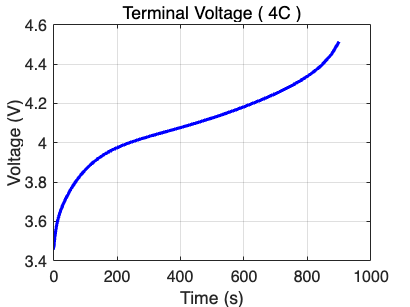

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% 1) 设定仿真参数 (例如 1C 放电或充电)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Crate = 4;  % 例如 -1C 表示放电, +1C 表示充电
I_app = Crate * para.C_nom / para.As;  
% 依据你的符号约定, 可能需要 para.I_app = -I_app
para.I_app = -I_app;

% 仿真时长: 若绝对值为1C, 则1小时=3600s; 2C 则 1800s 等
para.time_span = [0, 3600 / abs(Crate)];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% 2) 设定初始浓度 (根据放电或充电从不同SOC开始)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if I_app >= 0  
    % 充电时: 从低SOC开始
    c_n0 = para.soc0_a * para.cs1_max;  % 负极
    c_p0 = para.soc0_c * para.cs3_max;  % 正极
else
    % 放电时: 从高SOC开始
    c_n0 = para.soc1_a * para.cs1_max;
    c_p0 = para.soc1_c * para.cs3_max;
end

% 拼接初始状态向量: 负极 (Nr_anode+1 个节点) + 正极 (Nr_cathode+1 个节点)
x0 = [ repmat(c_n0, para.Nr_anode+1, 1); 
       repmat(c_p0, para.Nr_cathode+1, 1) ];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% 3) 运行 ODE 求解
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
[t_sol, x_sol] = ode15s(@(t,x) spm_ode_system(t, x, para), ...
                        para.time_span, x0, opts);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% 4) 计算各时刻的端电压
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
V_cell = zeros(size(t_sol));
for k = 1:length(t_sol)
    % x_sol(k,:) 是在时刻 t_sol(k) 的状态向量
    V_cell(k) = compute_terminal_voltage(x_sol(k,:)', para);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% 5) 绘制 "Terminal Voltage vs Time"
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure('Name','Terminal Voltage vs Time');
plot(t_sol, V_cell, 'LineWidth',2, 'Color','b');
xlabel('Time (s)');
ylabel('Voltage (V)');
title(['Terminal Voltage ( ' num2str(Crate) 'C )']);
grid on;


% 在命令行窗口打印最终时刻的电压值
fprintf('Final terminal voltage at t=%.1f s: %.2f V\n', t_sol(end), V_cell(end));

Final terminal voltage at t=900.0 s: 4.51 V
